## **9. gyakorlat**

#### **1. Feladat**

Interpoláljuk az $f(x)=\sin\left(\frac{\pi}{2}x\right)$ függvényt a $-1,0,1$ alappontokon

a) másodfokú spline-nal $f'(-1)=0$ peremfeltétellel,

b) harmadfokú spline-nal, Hermite-féle peremfeltétellel: $f'(-1)=f'(1)=0$.

A lineáris egyenletrendszereket oldjuk meg a MATLAB-bal, majd rajzoljuk ki a függvényt és a megoldásokat! Harmadfokú esetben is részintervallumonként rajzoljuk! 

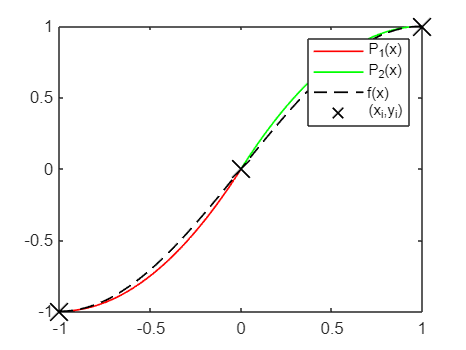

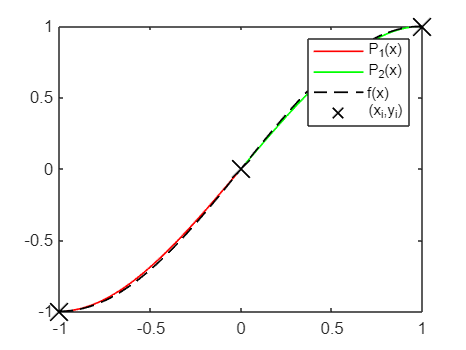

% Megoldás

f=@(x) sin(x*pi/2);
x=[-1,0,1];

% spldrawer(x,f,P);

#### 2. Feladat

Készítsünk másodfokú splinet, amely interpolál az `x(i), y(i)` pontokban $(i=1,\dots,n)$. A peremfeltétel legyen az `x(1)` pontbeli derivált értéke: `m`.  Határozzuk meg a spline-t definiáló `n-1` db másodfokú polinomot, és rajzoljuk fel a spline-t! A kiértékelésnál használjuk a MATLAB `polyva`l utasítását (megfelelő paraméterrel). A képletek a 7. előadás diái között megtalálhatóak. A fájl neve legyen` spl2.m`.

Bemenő paraméterek: 

- `x`: az alappontok vektora`, `

- `y:` a függvényértékek vektora,

- m: a baloldali végpontban a derivált értéke

Kimenő paraméter: 

- `P:`mátrix, mely a soraiban az intervallumonként megadott polinomok együtthatóit tartalmazza az $(x-x_i)$ hatványai szerint.  

a) Próbáljuk ki a programot az $f(x)=\sin\left(\frac{\pi}{2}x\right)$ függvény interpolációjára a $-1,0,1$ alappontokon különböző $m$ értékek mellett!

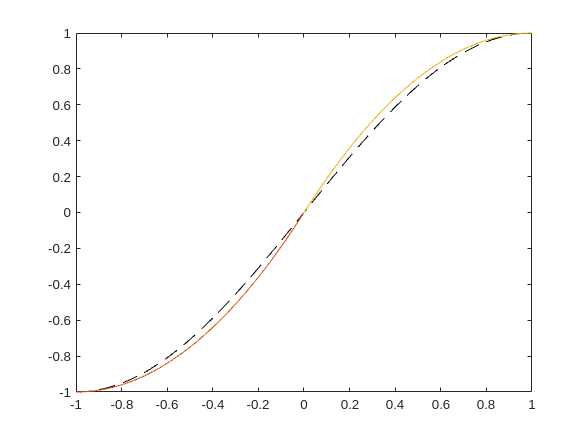

x = [-1,0,1]; 
y = sin(pi/2*x);
xx = linspace(-1,1,100); 
yy = sin(pi/2*xx);
plot(xx,yy,'k--')

hold on
spl2(x,y,0);
hold off

b) Próbáljuk ki a programot ugyanezen függvény interpolációjára az $x_i=i$ alappontokon az $m=\frac{\pi}{2}$ derivált értékkel! Próbálkozzunk más derivált értékekkel is!

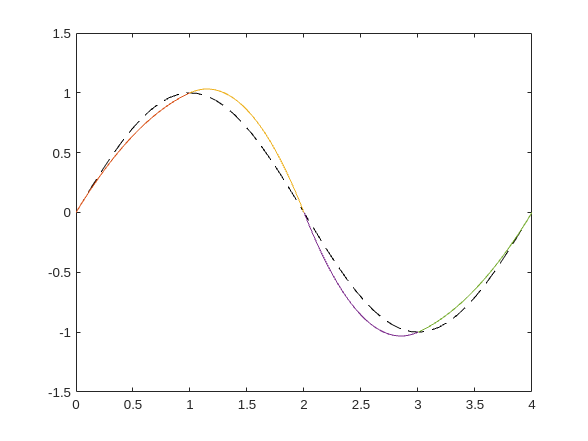

x = 0:4; 
y = sin(pi/2*x);
xx = linspace(0,4,50); 
yy = sin(pi/2*xx);
plot(xx,yy,'k--')
hold on
spl2(x,y,pi/2);
hold off

#### **1. Példa**

Készítsünk harmadfokú spline-t, amely interpolál az `x(i), y(i)` pontokban $(i=1,...,n)$. A hiányzó peremfeltételek legyenek az `x(1)` pontbeli első és második derivált értékek: `m1, m2`. Határozzuk meg a spline-t definiáló `n-1` db másodfokú polinomot, és rajzoljuk fel a spline-t!

Ez nem egy klasszikus peremfeltételű spline, nem is közelít jól. Az `spl2.m` függvényhez hasonlóan Hermite-interpolációt használunk hozzá. Vezessük le ezeket a képleteket először táblán/papíron, majd nézzük meg az `spl3.m` függvény kódját!

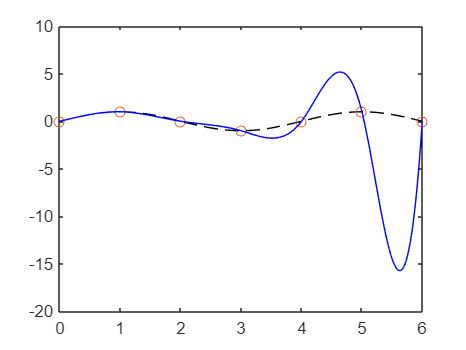

x = 0:6;
y = sin(pi/2*x);
xx = linspace(0,6,50);
yy = sin(pi/2*xx);
plot(xx,yy,'k--')
hold on
spl3(x,y,pi/2,0);
hold off

#### `A MATLAB beépített függvényei`

`spline(x,y,xx): K`öbös spline-t állít elő. `x`-ben vannak az alappontok, `y`-ban a függvényértékek. Az xx vektorban megadott értékekre számítja ki a spline értékét. 

- Ha az x és y vektor azonos elemszámú, akkor a „not-a-knot” feltétellel dolgozik, ami azt jelenti, hogy az első részintervallum végén és az utolsó elején az  feltételt is megköveteli, ez a két plussz feltétel az egyértelműséghez. Mivel harmadfokú a spline, ez azt jelenti, hogy az első két és utolsó két intervallumon egy harmadfokú polinomot adunk meg két intervallumra.

- Ha az y vektor kettővel nagyobb elemszámú, akkor az első és utolsó y-beli elem a két végpontbeli derivált értékeket tartalmazza, azaz Hermite-féle feltétellel dolgozik, ez a két plussz feltétel az egyértelműséghez.

`spline(x,y): K`öbös spline-t állít elő. `x`-ben vannak az alappontok, `y`-ban a függvényértékek. Az intervallumonkénti polinom előállítást adja meg, ami a `ppval `utasítással értékelhető ki. Érdemes még megnézni az `mkpp, unmkpp `utasításokat, melyek szintén az intervallumonkénti polinomokkal dolgoznak.

`pchip(x,y,xx): `Szakaszonkénti köbös Hermite interpolációt állít elő. `x`-ben vannak az alappontok, `y`-ban a függvényértékek. Az `xx` vektorban megadott értékekre számítja ki a görbe értékét. A kimenetként kapott $S$ görbe interpolál az `x`-ben megadott pontokon, továbbá $S' \in C$, de a második derivált nem feltétlenül folytonos. Egy részintervallumon a két végpontbeli függvényértékből és a derivált értékekből dolgozik. Megőrzi a monotonitást, ha az adatok ilyenek, akkor $S$ is ilyen lesz. (Ezt a spline nem tudja.) Ahol az adatoknak szélsőértéke van, ott $S$-nek is. Sima (ahol a magasabb deriváltak is folytonosak) függvények esetén a spline ad jobb közelítést.

`pchip(x,y): `Az előző MATLAB függvény szakaszonkénti polinom (*piecewise polynomial*) alakja.

**2. Példa**

A következő programokkal a `pchip` és a MATLAB által megvalósított kétféle peremfeltételű spline közelítését hasonlítjuk össze egy példán.

**a) Összehasonlító példa spline-ra és pchip-re:**

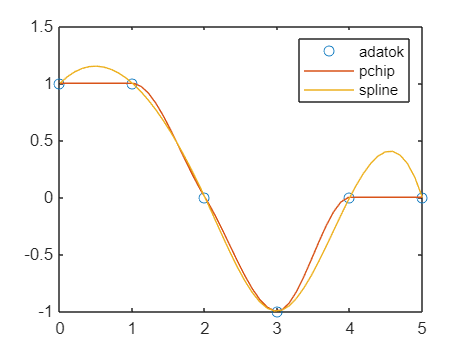

x1 = 1:4; 
y1 = sin(pi/2*x1);
x2 = 0:5;
y2 = [1,y1,0];
xx = linspace(0,5,50);
yy1 = pchip(x2,y2,xx);
yy2 = spline(x2,y2,xx); % ’not a knot’ spline
plot(x2,y2,'o',xx,yy1,xx,yy2)

legend('adatok','pchip','spline')

**b) Összehasonlítás pchip-re és Hermite-féle spline-ra:**

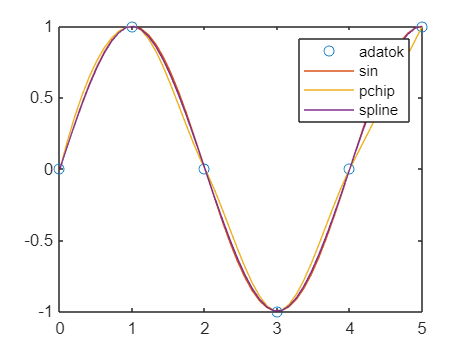

x2 = 0:5;
y2 = sin(pi/2*x2);
xx = linspace(0,5,50);
yy = sin(pi/2*xx);
yy1 = pchip(x2,y2,xx);
yy2 = spline(x2,[pi/2,y2,0],xx); % Hermite peremfeltételű spline
plot(x2,y2,'o',xx,yy,xx,yy1,xx,yy2);

legend('adatok','sin','pchip','spline')

**c) Összehasonlítás a kétféle peremfeltételre (not-a-knot, Hermite-féle):**

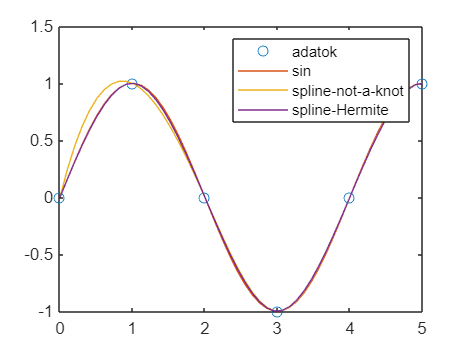

x2 = 0:5;
y2 = sin(pi/2*x2);
xx = linspace(0,5,50);
yy = sin(pi/2*xx);
yy1 = spline(x2,y2,xx); % not-a-knot peremfeltételű spline
yy2 = spline(x2,[pi/2,y2,0],xx); % Her+mite peremfeltételű spline
plot(x2,y2,'o',xx,yy,xx,yy1,xx,yy2);

legend('adatok','sin','spline-not-a-knot','spline-Hermite')